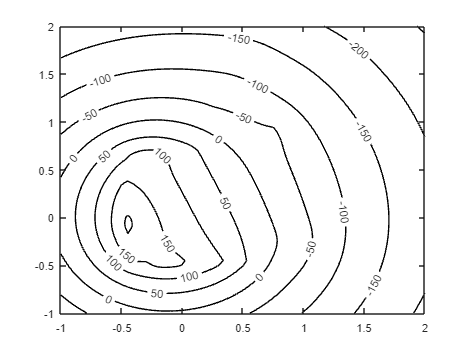

[x,y]=meshgrid(-1:0.05:2,-1:0.05:2);
% define the potential at all mesh points

v = log(sqrt((x-0.244).^2+(y-1.128).^2));

global_points = globalCleaned;
i = 1;
while i < 244
    x_coord = global_points(1,i);
    y_coord = global_points(2,i);
    v = build_equation(v, x, y, x_coord, y_coord);
    i = i + 1;
end

% plot contours with levels marked
contour(x,y,v,'k','ShowText','On')

function [v] = build_equation(v, x, y, x_coord, y_coord)
    v = v - (log(sqrt((x-x_coord).^2+(y-y_coord).^2)));
end